Companion software for "Volker Ziemann, *Physics and Finance, Springer, 2021*" ([https://link.springer.com/book/10.1007/978-3-030-63643-2](https://link.springer.com/book/10.1007/978-3-030-63643-2))

# Multi-fractal walks (Section 9.6)

Volker Ziemann, 211116, CC-BY-SA-4.0

This example shows the generation  of the **uni-fractal **and** multi-fractal walks** shown in Figure 9.7 and 9.8, where we can select the latter by selecting the checkbox at the start of the script. The slider allows to specify an increased waiting time in order to watch the fractal develop. 

scramble=true; % uni or multi-fractal
waiting_time=0.1;

The array `p` describes the start and end point of the fractal walk, whereas `dp` is the vector pointing from start to end point.

p=[0,0; 1,1];        % start and end point
dp=p(2,:)-p(1,:);    % vector from start to end point

The fractals are generated by two control points `pa` and` pb`, which define a small detour of the walk. This detour generator, plotted in the upper panel, is subsequently used to generate the same-shaped detour on every line segement, which is the "rule" that generates the uni-fractal. 

pa=[4/9,2/3];            % control points for the generator
pb=[5/9,1/3];            % play with these numbers
q0=nextiter(p,pa,pb,0);  % show generator points
subplot(2,1,1); plot(q0(:,1),q0(:,2),'k')

Now we iterate for a number of generations. In each generation, we determine the number `N` of points in the walk, defined by `p`, and allocate an array `p2` to contain the next-generation walk. 

for generation=1:10
    N=size(p,1);       % number of points 
    p2=zeros(3*N,2);

In the next snippet, w loop over the line segments and call the function nextiter(), defined in the appendix, to calculate the intermediate detour-points on the segment, which we then add to` p2`.

    mm=1;
    for m=1:2:N-1      
        p2(mm:mm+5,:)=nextiter(p(m:m+1,:),pa,pb,scramble);  
        mm=mm+6;
    end

before the next generation we display the present walk p2, and copy p2 back to p, so we can start the next iteration. The small pause allows us to inpsect the generation of the walk, as it is generated generation by generation.

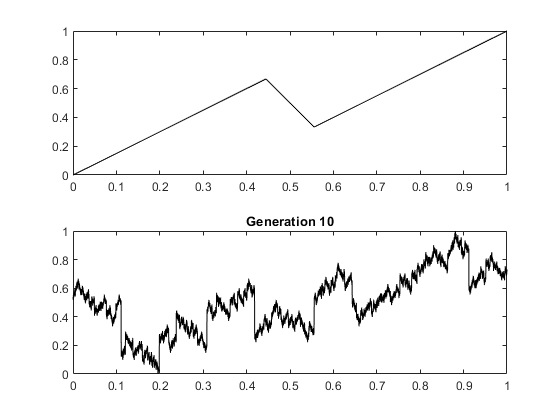

    subplot(2,1,2);  plot(p2(:,1),p2(:,2),'k') 
    title(['Generation ',num2str(generation)])
    p=p2;   % copy back for next iteration
    pause(waiting_time)
end

Once the walk is constructed, we calculate its "derivative", which we interpret as daily (or weekly) increments and plot te in the upper panel. The lower panel shows a histogram that is calculated by binning the increments into 100 bins.

jump=7         % steps for the derivative calculation

jump = 7

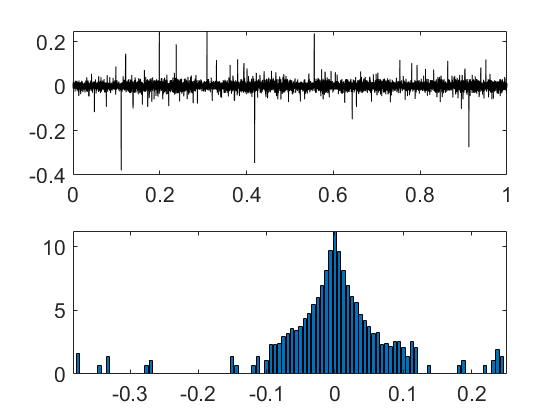

d=p2(jump:end,2)-p2(1:end-jump+1,2);  % "derivative" = increments
figure; subplot(2,1,1); plot(p2(jump:end,1),d,'k'); 
set(gca,'FontSize',16)
[height,pos]=hist(d,100);             % histogram of increments
subplot(2,1,2); bar(pos,log(height));  
set(gca,'FontSize',16) 

And now you can play with the parameters, for example the control points `pa `and `pb` for the detour, or `jump`, which is used to calculate the increments.

## Appendix

The function `nextiter()` receives `p`, which describes a two-point segment of a walk and the control points for the detour `pa, pb`, as well as the variable `scramble`, which is either 0 or 1 and controls whether we create a uni- or multi-fractal. The function returns six points of the corresponding segment, but with the detour added. First we add the two additional points, but note that point 2 and 3 as well as point 4 and 5 are the same.

function q=nextiter(p,pa,pb,scramble)
q=zeros(6,2);
dp=p(2,:)-p(1,:);
q(1,:)=p(1,:);
q(2,:)=p(1,:)+[pa(1)*dp(1),pa(2)*dp(2)];
q(3,:)=q(2,:);
q(4,:)=p(1,:)+[pb(1)*dp(1),pb(2)*dp(2)];
q(5,:)=q(4,:);
q(6,:)=p(2,:);

Doubling the intermediate points is necessary for cases where `scramble` is 1, because we randomly exchange the three sub-segments. In the first lines we prepare a random permutation of the integers 1, 2 and 3 and store them in `a,b,` and` c`.

if scramble
    qq=q;    
    a=1+floor(3*rand);
    b=1+floor(3*rand);
    while (a==b)
        b=1+floor(3*rand);
    end
    c=(6/a)/b;

Then we calculate by how much we have to horizontally move the segments by dax and dbx and subsequently move and permute the sub-segements at the same time

    dax=qq(2*a,1)-qq(2*a-1,1);
    dbx=qq(2*b,1)-qq(2*b-1,1);
    q(1,1)=p(1,1);
    q(1,2)=qq(2*a-1,2);
    q(2,1)=p(1,1)+dax;
    q(2,2)=qq(2*a,2);
    q(3,1)=q(2,1);
    q(3,2)=qq(2*b-1,2);
    q(4,1)=q(2,1)+dbx;
    q(4,2)=qq(2*b,2);
    q(5,1)=q(4,1);
    q(5,2)=qq(2*c-1,2);
    q(6,1)=p(2,1);
    q(6,2)=qq(2*c,2);
end
end